### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000; 

### Initialize the function

im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=64);

### Get many realizations of total wave energy for each K,j

% interp G
zvect = linspace(-im.Lz, 0, 1000);  % Depth vector
FInterp = im.scatteredInterpolation(im.F, zvect, im.KRadialLog, im.j);
GInterp = im.scatteredInterpolation(im.G, zvect, im.KRadialLog, im.j);

TEPrefactor = @(k,j) 1;
HKEPrefactor = @(k,j) 1 + 1./(1 + im.Lr2(j)*k.*k);
VKEPrefactor = @(k,j,indk) k^2.*im.h(j,indk)^2;
PEPrefactor = @(k,j,indk) (k^2.*im.h(j,indk)^2)./(im.omega(j,indk)^2);

for indK = 1:length(im.KRadialLog)
    if indK == 1
        % First Interval
        lowerBound = 0;  % Use um valor pequeno para evitar zero
        upperBound = im.KRadialLog(indK)/2;
    elseif indK == length(im.KRadialLog)
        % Last Interval
        lowerBound = upperBound;
        upperBound = im.KRadialLog(indK);
    else
        % Others Intervals
        lowerBound = upperBound;
        upperBound = im.KRadialLog(indK) + (im.KRadialLog(indK + 1) - im.KRadialLog(indK) )/2;
    end
    for indj = 1:length(im.j)
        sigma2 = im.E_T.* im.M(im.j(indj)) .*...
             integral(@(k) im.B(k,im.j(indj)), lowerBound, upperBound);
        E_njk(:,indj,indK) = sigma2*(randn([1 200])).^2;

    end
end

for indK = 1:length(im.KRadialLog)
    for indj = 1:length(im.j)
        for indz =1:length(zvect)

           HKE(:,indz,indj,indK)= E_njk(:,indj,indK).* (1/(2*im.h(indj,indK))).*...
               HKEPrefactor(im.KRadialLog(indK),im.j(indj)).*FInterp(indz,indj,indK).^2;

           VKE(:,indz,indj,indK)= E_njk(:,indj,indK).* (1/(2*im.h(indj,indK))).*...
               VKEPrefactor(im.KRadialLog(indK),im.j(indj),indK).*GInterp(indz,indj,indK).^2;

           PE(:,indz,indj,indK)= E_njk(:,indj,indK).* (1/(2*im.h(indj,indK))).*...
               PEPrefactor(im.KRadialLog(indK),im.j(indj),indK).*im.N2(zvect(indz)).*GInterp(indz,indj,indK).^2;

        end
    end
end

HKE=sum(sum(HKE,4),3);
VKE=sum(sum(VKE,4),3);
PE=sum(sum(PE,4),3);

for zind = 1:length(zvect)
     HKE_q25(zind) = prctile(abs(HKE(:,zind)), 25);
     HKE_q75(zind) = prctile(abs(HKE(:,zind)), 75);

     VKE_q25(zind) = prctile(abs(VKE(:,zind)), 25);
     VKE_q75(zind) = prctile(abs(VKE(:,zind)), 75);

     PE_q25(zind) = prctile(abs(PE(:,zind)), 25);
     PE_q75(zind) = prctile(abs(PE(:,zind)), 75);
end

HKE_mean = mean(abs(HKE),1);
VKE_mean = mean(abs(VKE),1);
PE_mean = mean(abs(PE),1);

### Computing variance from the toolbox

HKEVerticalVariance = im.verticalVariance('HKE', 'zVector', zvect, 'Plot', 0,'Mask',0);  % Vertical variance
VKEVerticalVariance = im.verticalVariance('VKE', 'zVector', zvect, 'Plot', 0,'Mask',0);  % Vertical variance
PEVerticalVariance = im.verticalVariance('PE', 'zVector', zvect, 'Plot', 0,'Mask',0);  % Vertical variance

### Plotting

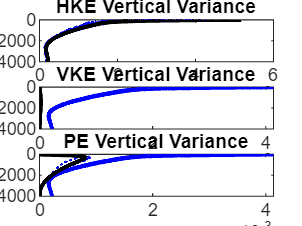

% Create a new figure
figure;

% Define the 3x1 grid layout for the subplots
subplot(3, 1, 1); 
plot(HKE_mean,zvect,Color='b',LineWidth=2)
hold on
plot(HKE_q25,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(HKE_q75,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(HKEVerticalVariance,zvect,Color='k',LineWidth=2)
title('HKE Vertical Variance');
ylabel('depth [m]')

%
subplot(3, 1, 2); 
plot(VKE_mean,zvect,Color='b',LineWidth=2)
hold on
plot(VKE_q25,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(VKE_q75,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(VKEVerticalVariance,zvect,Color='k',LineWidth=2)
title('VKE Vertical Variance');
ylabel('depth [m]')

%
subplot(3, 1, 3); 
plot(PE_mean,zvect,Color='b',LineWidth=2)
hold on
plot(PE_q25,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(PE_q75,zvect,Color='b',LineWidth=1,LineStyle=':')
plot(PEVerticalVariance,zvect,Color='k',LineWidth=2) 
title('PE Vertical Variance');
ylabel('depth [m]')


% Add a main title for the figure
%sgtitle('Figure with 3 Panels (1 Column Layout)');